### **Audio Spectral Analysis:**

**Set parameters:**

Fs=96000; %Sampling frequency in hertz (Hz)
NBITS=24;%Bits per sample.
NCHAN=1; %Channel Number
duration = 6.0; %seconds

duration = 6

**Load existing audio file:**

%to load back
%[y,Fs] = audioread('audio2.wav'); 

**Record Audio:**

%record audio
r=audiorecorder(Fs,NBITS,NCHAN);
record(r);
pause(duration);
stop(r);
%save audio
y =getaudiodata(r,'double');
filename = 'output.wav';
audiowrite(filename, y, Fs)

**Visualise Signal and Generate Spectrogram**


%visualise signal and generate spectrogram

window_size_t = 0.002; %seconds

window_size_t = 0.0020

window_size = round((window_size_t/duration)*size(y,1));

window_size = 190

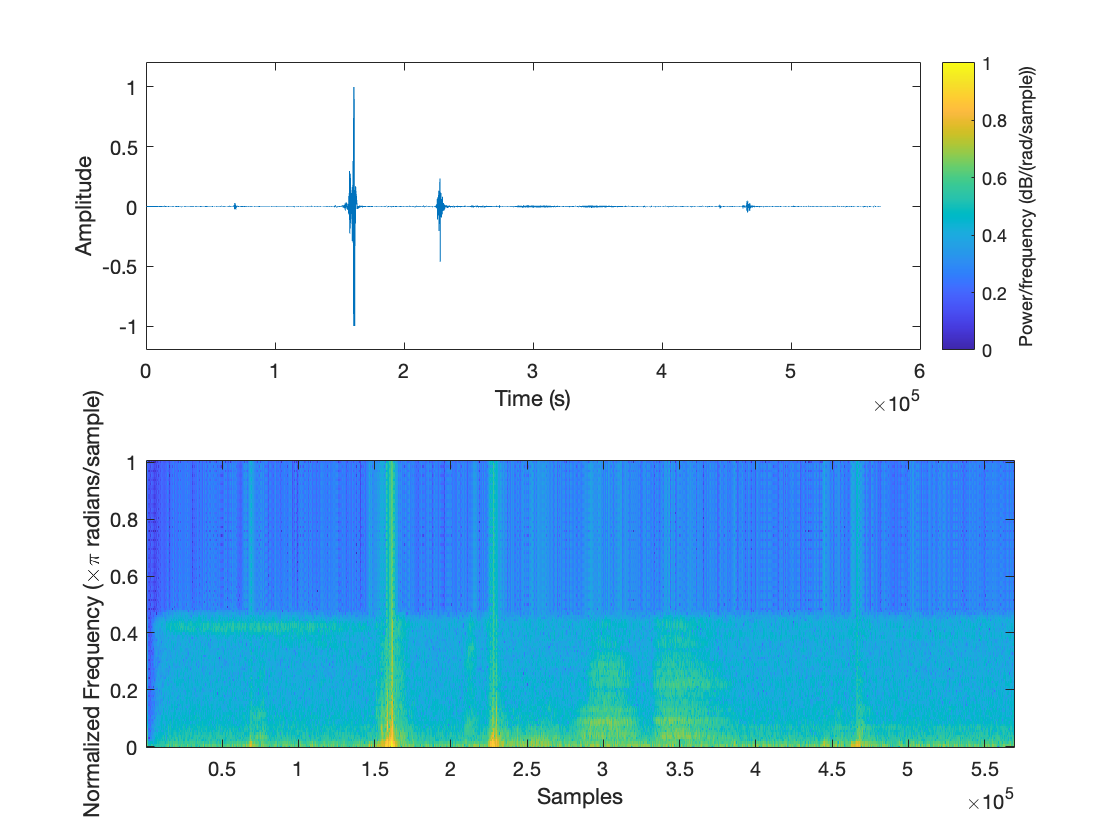


subplot(2,1,1)
plot(y)
xlabel('Time (s)')
ylabel('Amplitude')
ylim([-1.2 1.2])

subplot(2,1,2)
spectrogram(y,window_size,round(window_size*0.5),'yaxis')